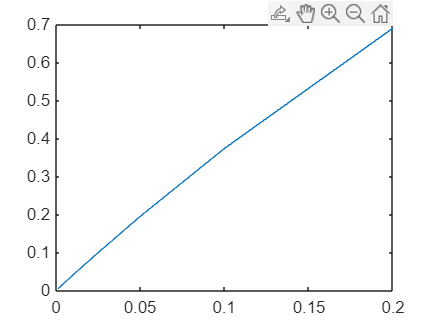

clc;
clear;
f =@(x,y) y + 2*(1-x);
g =@(t) 2*t +3*exp(t);
h = [0.2 0.1 0.05 0.025 0.02 0.0125 0.01 0.00625 0.003125 0.002 0.001];
f1_value = zeros(1,length(h));
f1_error = zeros(1,length(h));
f1_real = g(1);
for i = 1 : length(h)
    f1_value(i) = euler_diff(0,1,3,h(i),f);
    f1_error(i) = abs(f1_value(i)-f1_real);
end
plot (h,f1_error);

function[output] = euler_diff(start,End,fstart,h,f)
n = (End - start)/h;
x = zeros(1,n);
y = zeros(1,n);
for i = 1 : n
    x(i) = start;
    start = start + h;
end
y(1) = fstart;
for i = 1 : n
    y(i+1) = y(i) + h*f(x(i),y(i));
end
output = y(n+1);
end